# Simulation of a phase-locked loop

Author: Christoph Kaufmann

Date: 10.03.2025

Summary: This scripts shows how a phase-locked loop (PLL) is modeled as an multilinear time-invariant (MTI) model and simulated using the MTI Toolbox [3]. It compares the results with the nonlinear model. 

clear; clc;

## 1. Derivation of the multilinear model of the PLL

We want to model the nonlinear synchronous reference frame phase-locked loop depicted in the following figure

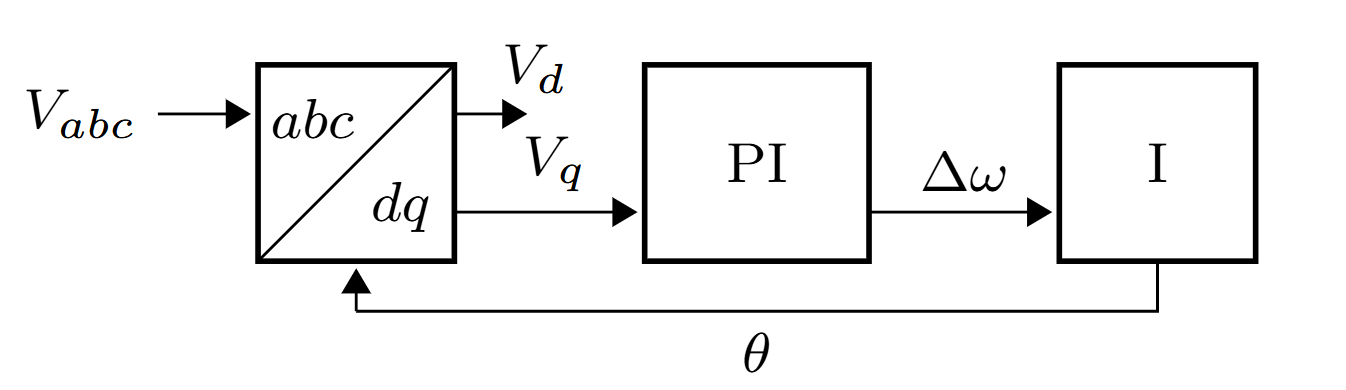,

where the q-component of the voltage is aligned with the phase a, and thereby, regulated to 0 for synchronization. Using trigonometric identities, we can derive the following continuous-time, time-invariant second-order model 

$\dot{\theta}=x_\mathrm{I} + k_\mathrm{p}\frac{1}{3} \left(\left(-2 v_\mathrm{a} + v_\mathrm{b} +v_\mathrm{c}\right)\sin{(\theta)}+\sqrt{3}\left(v_\mathrm{b} - v_\mathrm{c}\right)\cos{(\theta)}\right) +\omega_0$, (1a)

$\dot{x}_\mathrm{I}=k_\mathrm{i} \frac{1}{3}\left(\left(-2 v_\mathrm{a} + v_\mathrm{b} +v_\mathrm{c}\right)\sin{(\theta)}+\sqrt{3}\left(v_\mathrm{b} - v_\mathrm{c}\right)\cos{(\theta)}\right) $,                 (1b)

where $x_{\mathrm{I}}$ is the state of the first integrator in the PI-controller, $k_{\mathrm{p}}$ and $k_{\mathrm{I}}$are the corresponding gain values, $\theta$ is the estimated angle given by the second integrator. Note that the nominal angular grid frequency $\omega_0$  is added in (1). The three-phase voltages $v_{\textrm{abc}}$ are the inputs to the second-order model.

Motivated by the work [1,2], we introduce the following nonlinear change of variables [3]


$$\begin{array}{l}
x_1 =\cos \left(\theta \right),\;\;\;\left(2a\right)\\
{\;x}_2 =\sin \left(\theta \right),\;\;\left(2b\right)\\
{\;x}_3 =x_{\mathrm{I}} ,\;\;\;\;\;\;\;\;\;\;\;\left(2c\right)
\end{array}$$


and the algebraic constraint 

$x_1^2 +x_2^2 -1=0\ldotp$ (3)

Derivating (2) and inserting (1) into it leads to the multilinear model of (1) as

 $\dot{x}_1=\left(x_3 + k_\mathrm{p}\frac{1}{3} \left(\left(-2 v_\mathrm{a} + v_\mathrm{b} +v_\mathrm{c}\right)x_2+\sqrt{3}\left(v_\mathrm{b} - v_\mathrm{c}\right)x_1\right) +\omega_0\right)\cdot (-y_2) $, (4a)

$\dot{x}_2=\left(x_3 + k_\mathrm{p}\frac{1}{3} \left(\left(-2 v_\mathrm{a} + v_\mathrm{b} +v_\mathrm{c}\right)x_2+\sqrt{3}\left(v_\mathrm{b} - v_\mathrm{c}\right)x_1\right) +\omega_0\right)\cdot (y_1) $,    (4b)

$\dot{x}_3=k_\mathrm{I}\frac{1}{3} \left(\left(-2 v_\mathrm{a} + v_\mathrm{b} +v_\mathrm{c}\right)x_2+\sqrt{3}\left(v_\mathrm{b} - v_\mathrm{c}\right)x_1\right) $,                                 (4c)

$y_1 =x_1$,                                                                                              (4d)

$y_2 =x_2$,                                                                                              (4e)

where $y_1$, $y_2$ are auxilary algebraic variables to avoid having squares of the variables, which would escape the multilinear modeling class. The multilinear system of differential-algebraic equations  (4) is square without the algebraic constraint (3). The algebraic constraint (3) is used to find consistent initial conditions for the system of differential-algebraic equations. 

We can now write (4) as an implicit multilinear-time invariant (iMTI) model using the MTI Toolbox.

## 2. Programming the Multilinear Model using the MTI Toolbox 

### 2.1 Implicit multilinear state-space equaions

We choose writing (4) as symbolic equations

eqs={'0==-xp1+(x3+Kp_PLL*1/3*((-2*u1+u2+u3)*x2+sqrt(3)*(u2-u3)*(x1))+wnom)*(-y2)';
     '0==-xp2+(x3+Kp_PLL*1/3*((-2*u1+u2+u3)*x2+sqrt(3)*(u2-u3)*(x1))+wnom)*y1'; 
     '0==-xp3+(Ki_PLL*1/3*((-2*u1+u2+u3)*x2+sqrt(3)*(u2-u3)*(x1)))';   
     '0==y1-x1';
     '0==y2-x2'};

where xp denotes $\dot{x}$, and u1, u2, and u3, are the three-phase input voltages.    

### 2.2 Create dmss object from symbolic equations

The dmss-object is suitable for iMTI models. From the symbolic equations in eqs, we can create a dmss-object

sys=sym2dmss(eqs,0)

Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.


sys =   dmss with properties:

                          H: [1×1 hyCPN1]
                          n: 3
                          m: 3
                          p: 2
                          q: 0
                outputIndex: [1×1 struct]
                        nEq: 5
                      nIneq: 0
                  stateName: [0×0 string]
                  stateUnit: [0×0 string]
              algebraicName: [0×0 string]
              algebraicUnit: [0×0 string]
                  inputName: [0×0 string]
                  inputUnit: [0×0 string]
                booleanName: [0×0 string]
                booleanUnit: [0×0 string]
        manipulatedVariable: []
        measuredDisturbance: []
      unmeasuredDisturbance: []
                         ts: 0
    discreteDifferentiation: "none"


Now we need to replace the symbolic parameters with numerical values. We first define the values

% PLL tuning
    Kp=0.2732;
    Ti=0.08239;
    w0=2*pi*50;
    
    kp_PLL=Kp;
    ki_PLL=Kp*Ti;

and the we replace the symbolic values in the equations with the values 

new = [w0 kp_PLL ki_PLL];
syms wnom Kp_PLL Ki_PLL
old = [wnom Kp_PLL Ki_PLL];
sys=sys.replaceSymbolicParameters(old,new); 

### 2.3 Initial conditions

Lastly, we need to define the consistent initial conditions using (3). Assuming that the system starts at zero, we calculate

% initial conditions nonlinear model 
    theta_0=0;
    x_I_0= 0; 
    
% initial conditions iMTI model
    x1_0=cos(theta_0);
    x2_0=sin(theta_0);
    y1_0=x1_0;
    y2_0=x2_0;
    test=x1_0*y1_0+x2_0*y2_0-1;

    x3_0=x_I_0;
    x0MTI=[x1_0;x2_0;x3_0];

## 3. Simulation

### 3.1 Simulation time and input voltage

For the simulation, we define the timeseries of the input voltage.

% simulation time
    timeSimulation=0:0.001:3;

% frequency step from 50 Hz to 49.9 Hz at half the the simulation time
    wSimulation=[w0*ones(1,round(length(timeSimulation)/2)-1),2*pi*49.95*ones(1,round(length(timeSimulation)/2))];
    
% input voltage    
    inputVoltage=230*sqrt(2)*[sin(wSimulation.*timeSimulation);sin(wSimulation.*timeSimulation-2*pi/3);sin(wSimulation.*timeSimulation+2*pi/3)];

### 3.2 Solver settings

Both solver will have variable step sizes, though a maximum step size is provided. 

    opt=odeset('RelTol',1e-5,'AbsTol',1e-8,'MaxStep',1e-4);

### 3.3 Simulating nonlinear model

We simulate the nonlinear model, which is written in the function PLLnonlinear, using the ode45 solver and the default settings.  

% initial conditions
x0Non=[theta_0 x_I_0]; 

% simulate nonlinear model
tic
[tnon, xnon]=ode45(@(t,x)PLLnonlinear(t,x,kp_PLL,ki_PLL,w0,timeSimulation,inputVoltage),timeSimulation,x0Non,opt);
timeComputation_non=toc

timeComputation_non = 5.8771

For a better comparison later, we calculate the estimated frequency of the nonlinear model

freqNon=(kp_PLL*1/3*((-2*inputVoltage(1,:).'+inputVoltage(2,:).'+inputVoltage(3,:).').*sin(xnon(:,1))+sqrt(3)*(inputVoltage(2,:).'-inputVoltage(3,:).').*cos(xnon(:,1)))+w0+xnon(:,2))/(2*pi);

### 3.4 Simulating multilinear model

The dmsim simulates dmss-objects. It uses the ode15i, which is an implicit variable-step, variable-order method based on the backwards differentiation formula. Dmsim provides the Jacobian matrix as an additional argument to the solver to improve its performance. The initial conditions for the algebraic variables are automatically calculated using x0 and the input values at t=0. 

tic
simout= dmsim(sys, x0MTI,[],[],timeSimulation,inputVoltage.',opt); 
tcomp_mti=toc

tcomp_mti = 7.1799

We also calculate the estimated frequency of the iMTI model, 

inputVoltageMTI=interp1(simout.ut,simout.u,simout.tsim).';
freqMTI=(kp_PLL*1/3*((-2*inputVoltageMTI(1,:).'+inputVoltageMTI(2,:).'+inputVoltageMTI(3,:).').*simout.x(:,2)+sqrt(3)*(inputVoltageMTI(2,:).'-inputVoltageMTI(3,:).').*(simout.x(:,1)))+w0+simout.x(:,3))/(2*pi);
freqMTI=interp1(simout.tsim,freqMTI,tnon); % to get the frequency at the time steps of tnon

## 4. Comparison of results 

We can compare the results 

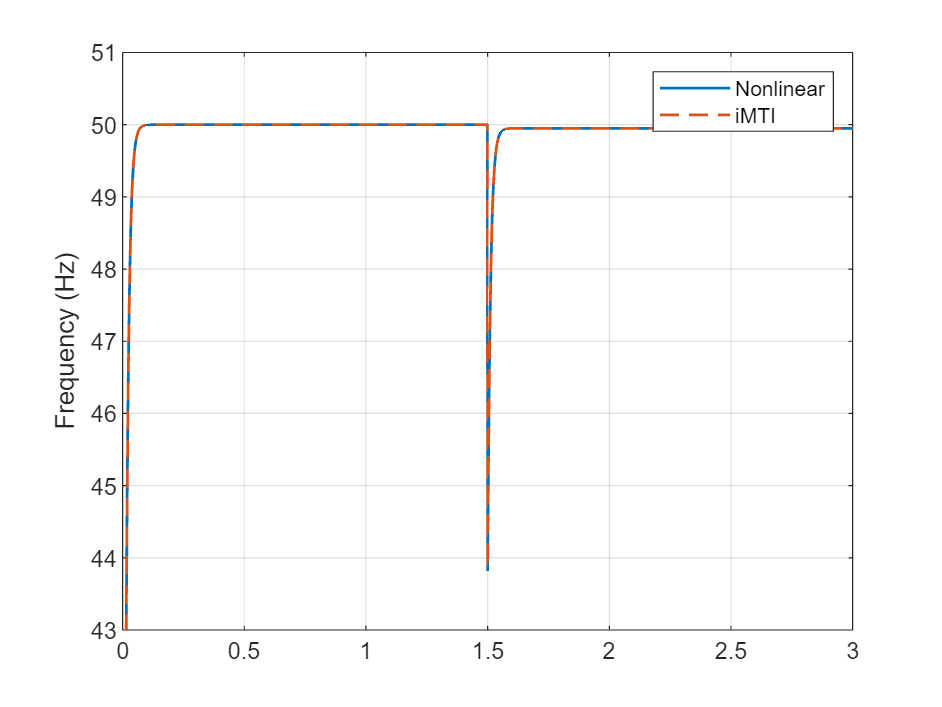

figure
plot(tnon,freqNon)
hold on
plot(tnon,freqMTI,'--')
ylabel('Frequency (Hz)')

legend('Nonlinear','iMTI')
ylim([43 51])
box on
grid on

The multilinear and the nonlinear model both estimate the same frequency. 

## 5. References 

[1] Savageau, M. A. and Voit, E. O. (1987). Recasting nonlinear differential equations as s-systems: a canonical nonlinear form. Mathematical Biosciences, 87(1):83–115.

[2] Anghel, M., Milano, F., and Papachristodoulou, A. (2013). Algorithmic construction of lyapunov functions for power system stability analysis. IEEE Transactions on Circuits and Systems I: Regular Papers, 60(9):2533–2546.

[3] Kaufmann, C., Pangalos, G., Lichtenberg, G. and Gomis-Bellmunt,O. (2025). Small-Signal Stability Analysis of Power Systems by Implicit Multilinear Models. Preprint available on arXiv.